## Variable Declaration - Motor on Spindle with Load

simtime = 26;           % simulation time in s
M_Mo = 6E-3;            % motorr torque in Nm
J_Mo = 5.0E-3;          % motor moment of inertia in Nm^2
i_G = 0.8;              % gear ratio
eta_G = 0.95;           % gear efficiency
eta_sp = 0.95;          % spindle efficiency
h_sp = 1E-03;           % spindle pitch
M = 1;                  % spindle mass in kg
F_L = 5;                % load force in N

## Simulation of Motor on Spindle with Load

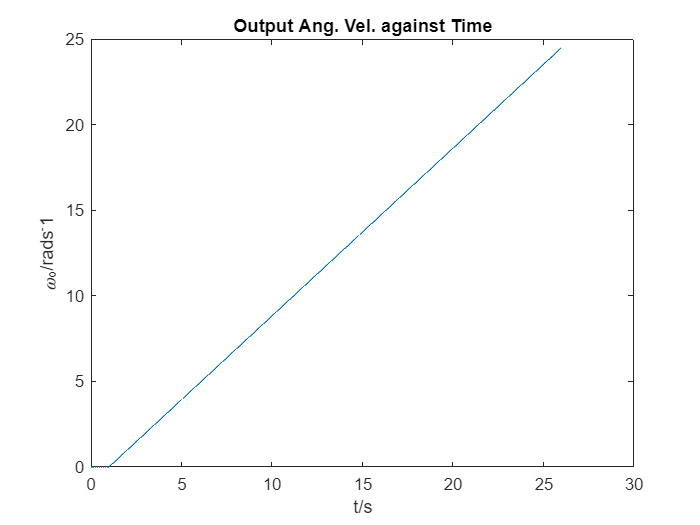

sim('Motor_Spindle_with_Load.slx')
figure
plot(W_Mo.time, W_Mo.data)
title('\omega_M_o against Time')
xlabel('t/s')
ylabel('\omega_M_o/rads^-1')

## Variable Declaration - Centrifugal Pump

J_CFP = 2E-2;
k = 6;
k_CFP = 10;
J_Fl = 7E-1;
R_CFP = 6;
M_in = 3E-3;

## Simulation of Centrifugal Pump

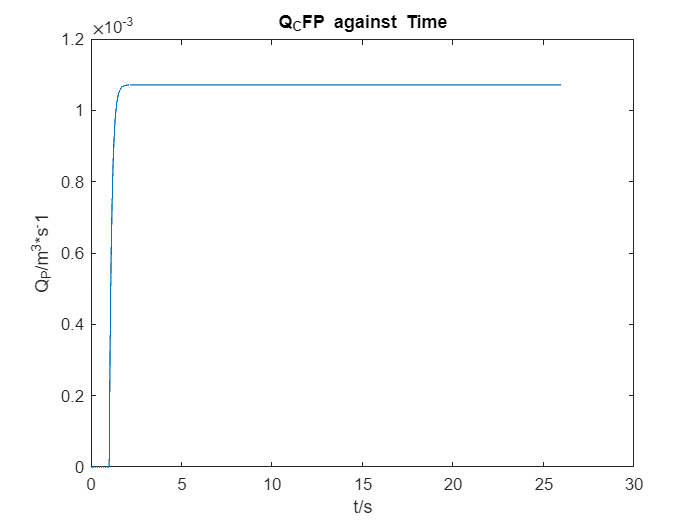

sim("Centrifugal_Pump.slx")
figure
plot(Q_CFP.time, Q_CFP.data)
title('Q_C_F_P against Time')
xlabel('t/s')
ylabel('Q_C_F_P/m^3*s^-1')

## Variable Declaration - Hydrostatic Displacement Pump

J_DP = 2E-2;
R_k = 5;
V_theo = 2E-2;
eta_vol = 0.95;
eta_hm = 0.95;
R_pipe = 6;
R_DP = 12;
L_FL = 8E-3;

## Simulation of Hydrostatic Displacement Pump

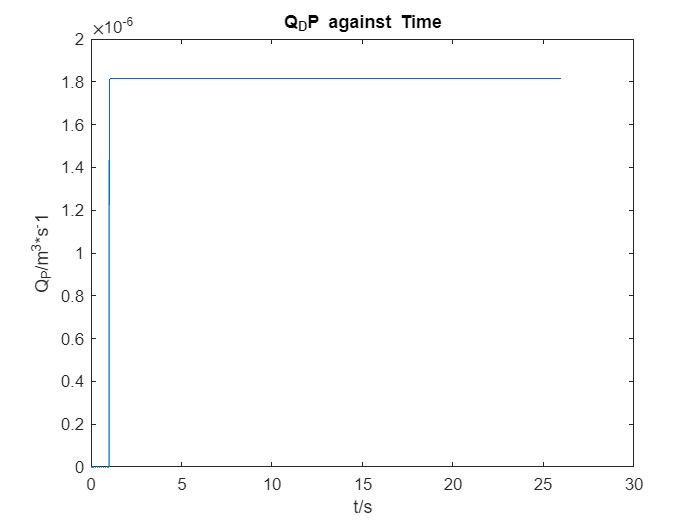

sim('Hydrostatic_Displacement_Pump.slx')
figure
plot(Q_DP.time, Q_DP.data)
title('Q_D_P against Time')
xlabel('t/s')
ylabel('Q_D_P/m^3*s^-1')